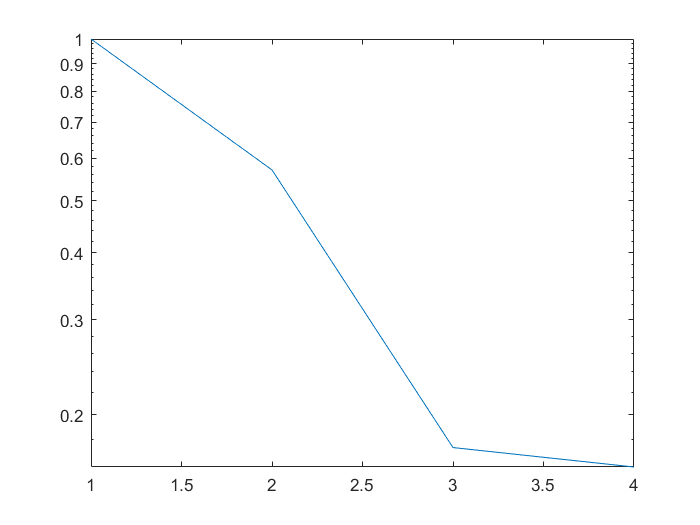

P = [1 1 2 2 -1 -2 -1 -2; 1 2 -1 0 2 1 -1 -2];
T = [-1 -1 -1 -1 1 1 1 1;-1 -1 1 1 -1 -1 1 1];
%T = [1 1 1 1 -1 -1 -1 -1;1 1 -1 -1 1 1 -1 -1];
W = [0 0;0 0];
b = [0;0];
%W = [1 0;0 1];
%b = [1;1];
L = 0.04;
threshold = 0.17;
mse_vector = [1];
i =1;

%Iterating over all 8 input patterns
while mse_vector(i) >= threshold
    %Each pattern is assumed to have NO errors
    tracker = zeros(2,8);
    for m = 1:8
        a =(W * P( :,m)) + b;
        e = T( :,m) - a;
        tracker( :,m) = e;
       
        %Update weight matrix and bias
        W = W + (2*L*e*transpose(P( :,m)));
        b = b + (2*L*e);
    end
    %Find mse of all patterns from an iteration
    mse_vector(i+1) = mse(tracker);
    i = i+1;
end

%Plot the learning error curve
semilogy(mse_vector)

%x = 1:(length(mse_vector)-1);
%y = mse_vector(2:end);
%semilogy(x,y);
%grid on

%Table of square error
out = purelin((W*P) + b);
vertical = {'Target 1'; 'Target 2'; 'Target 3'; 'Target 4'};
out1 = [mse(T( :,1)-out( :,1)); mse(T( :,3)-out( :,1)); mse(T( :,5)-out( :,1)); mse(T( :,7)-out( :,1))];
out2 = [mse(T( :,1)-out( :,2)); mse(T( :,3)-out( :,2)); mse(T( :,5)-out( :,2)); mse(T( :,7)-out( :,2))];
out3 = [mse(T( :,1)-out( :,3)); mse(T( :,3)-out( :,3)); mse(T( :,5)-out( :,3)); mse(T( :,7)-out( :,3))];
out4 = [mse(T( :,1)-out( :,4)); mse(T( :,3)-out( :,4)); mse(T( :,5)-out( :,4)); mse(T( :,7)-out( :,4))];
out5 = [mse(T( :,1)-out( :,5)); mse(T( :,3)-out( :,5)); mse(T( :,5)-out( :,5)); mse(T( :,7)-out( :,5))];
out6 = [mse(T( :,1)-out( :,6)); mse(T( :,3)-out( :,6)); mse(T( :,5)-out( :,6)); mse(T( :,7)-out( :,6))];
out7 = [mse(T( :,1)-out( :,7)); mse(T( :,3)-out( :,7)); mse(T( :,5)-out( :,7)); mse(T( :,7)-out( :,7))];
out8 = [mse(T( :,1)-out( :,8)); mse(T( :,8)-out( :,2)); mse(T( :,8)-out( :,8)); mse(T( :,7)-out( :,8))];

%Squared_error =
table(out1,out2,out3,out4,out5,out6,out7,out8,'RowNames',vertical)

ans = 4×8 table
                 out1       out2        out3       out4       out5       out6       out7        out8   
                _______    _______    ________    _______    ______    ________    _______    _________

    Target 1    0.42962    0.13213      2.5595     1.3412    1.2809      2.2528     2.5079       4.2329
    Target 2    0.83634     1.7887    0.038447    0.06995    3.7937      3.9438     1.2711       2.8196
    Target 3     1.4818     1.1631      4.7494     3.5099    0.1211    0.018778     1.4117    0.0040556
    Target 4     1.8885     2.8196      2.2284     2.2387    2.6339      1.7098    0.17493    0.0040556
